# Narrow down your legends with IconColumnWidth

MATLAB [Graphics and App Building Blog](https://blogs.mathworks.com/graphics-and-apps/)

Guest Writer: [Afiq Azaibi](https://www.mathworks.com/matlabcentral/profile/authors/8450560)

 [Afiq Azaibi](https://www.mathworks.com/matlabcentral/profile/authors/8450560) is back to tell us about a new feature in R2024b that controls the width of a legend. In this article, you'll learn about the new **IconColumnWidth** legend property.  Hearing directly from the developers of MATLAB graphics and app features is what this blog is all about!  See Afiq's bio on our [contributors page](https://blogs.mathworks.com/graphics-and-apps/contributors/). 

Legend and I were on a diet for 24b. While in the office, I was busy developing a way for users to make the legend narrower. While outside the office, I was busy trying to make myself narrower for my wedding. Let's take a look at how those two projects intersected.

tbl = readtable('weight.csv');
tbl = renamevars(tbl, ["Var1" "Var2"], ["Date", "Weight"]);
ax = axes;
scatter(ax, tbl, 'Date', 'Weight', 'DisplayName', 'My Weight');
ax.YLabel.String = "Weight in Pounds";
l = legend;

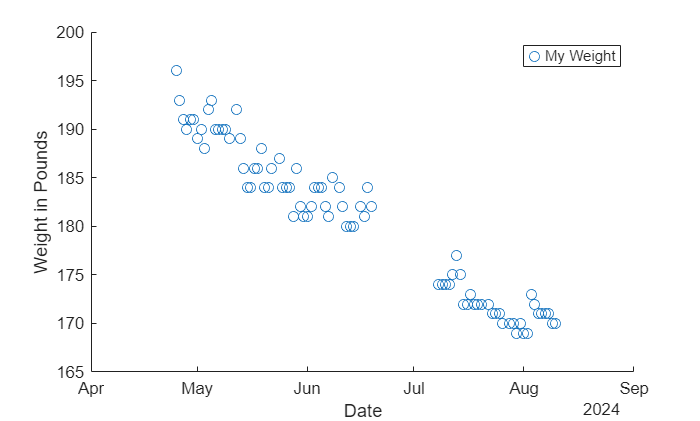

Each point in the scatter denotes a day that I weighed myself. The legend automatically clamps to a smaller size when there are only marker icons. You can see that there's a gap of time I didn't have access to a scale for 2 weeks. Let's highlight that gap of time with a [`ConstantRegion`](https://www.mathworks.com/help/matlab/ref/xregion.html) and while we're at it, also mark the wedding day with a [`ConstantLine`](https://www.mathworks.com/help/matlab/ref/xline.html). 

bachelorStart = datetime('21-June-2024');
bachelorEnd = datetime('6-July-2024');
bachelorParty = xregion(bachelorStart, bachelorEnd, 'DisplayName', 'Bachelor Party');
weddingDay = xline(datetime('10-August-2024'), 'r', 'DisplayName', 'Wedding Day');

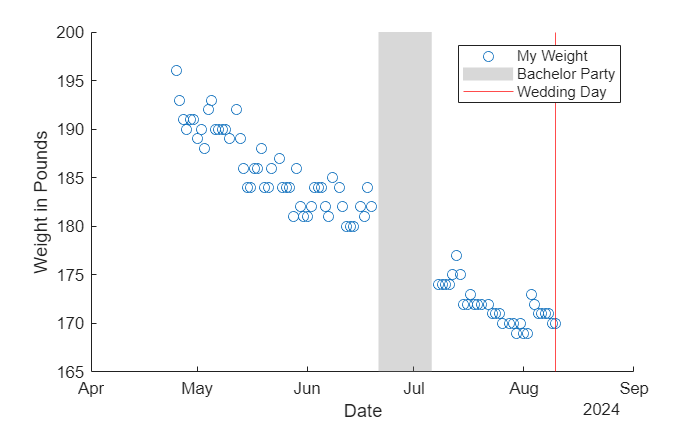

If you look at the legend, you'll notice that after we added the `ConstantRegion` and `ConstantLine`, there's a lot of padding surrounding the scatter icon. This happened because the icons in the legend are not exclusively markers. However the padding can be adjusted with the new [`IconColumnWidth`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.illustration.legend-properties.html#mw_a18598dd-6da8-49a6-93a3-3304acb675ec) property on legend. This property sets the width of the icon in points. If the legend does not automatically set this property the way you'd like, you can always override it. 

l.IconColumnWidth = 15;

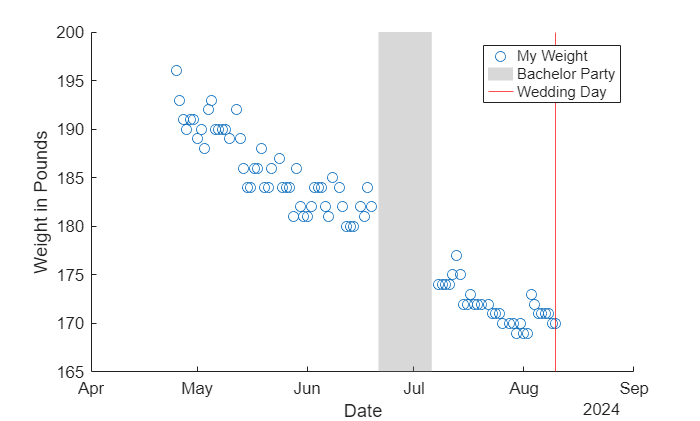

To make the ConstantRegion icon square, you can set the IconColumnWidth to the legend's FontSize property

l.IconColumnWidth = l.FontSize;

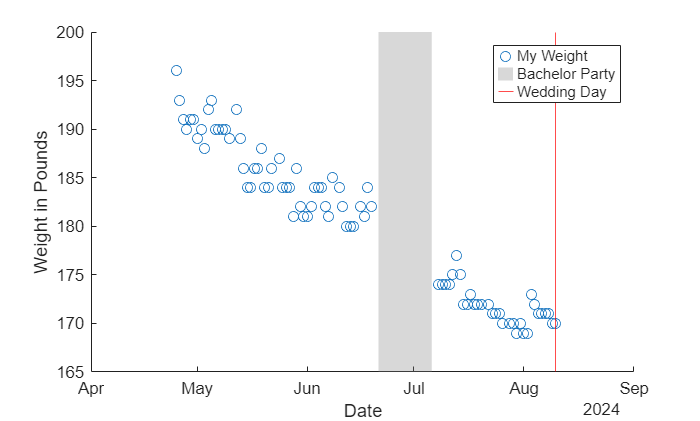

To recap, we've introduced `IconColumnWidth` and a new behavior for legend in 24b. The new behavior will automatically update the default value of `IconColumnWidth` when all the icons in the legend are markers. We made this decision to keep the heuristic relatively simple. Additionally, we did not want to change the default value in all cases since icons with non-solid lines get clipped such that it can become difficult to tell the difference between a non-solid line and solid line if `IconColumnWidth` is too small. 

Do you have a use case you're excited to apply this new feature to? Do you have ideas on how to improve its functionality? Please share them in the comments so we can continuously improve its design. 